# tuning V2 - octaves, plus lots of other analysis

% load raw traces 
addpath('456_1 flfl','456_2 tecta flfl','458_2 flfl','458_5 flfl','468_1 flfl','456_2 tecta flfl','460_2 tecta flfl','460_5 tecta flfl','460_6 tecta flfl','466_2 tecta flfl','480_2 tecta flfl','473_2 flfl','472_2 flfl','472_1 flfl','484_2 tecta flfl','488_1 tecta flfl','487_2 tecta flfl','486_1 flfl','487_1 flfl','505_2 tecta flfl','505_1 flfl')

con1 = load('C1-20211107 exp473mouse2 trmem16aflfl 3-24 khz tuning 10-60 db 4 rep 150 R IC_ICdata.mat'); % 473_2 R IC, poor quality
con2 = load('C1-20211103 exp472 mouse 2 tmem16aflfl 3-24 khz tuning log scale 10-60 4 rep L IC_ICdata.mat'); %472_2 L IC, better
con3 = load('C1-20211103 exp472 mouse 1 tmem16aflfl 3-24 khz tuning log scale 10-60 4 rep_ICdata.mat'); %472_1 flfl
con4 = load('C1-20211015 exp467 mouse 1 tmem16flfl 3-24 khz tuning 12 tones 4 rep 10-60 db atten_ICdata.mat'); %linear spacing
con5 = load('C1-exp456 m1 3-12khz 10-50 db 10 db steps 6 reps_ICdata.mat'); % linear spacing
con6 = load('C1-20211107 exp473mouse2 trmem16aflfl 3-24 khz tuning 10-60 db 4 rep 150_ICdata.mat'); % 473_2 L IC, poor quality
con7 = load('C1-20211220 exp487 mouse1 tmem16aflfl 3-24 khz tuning 10-60 db R IC 170 deep_ICdata.mat');
con8 = load('C1-20211220 exp487 mouse1 tmem16aflfl 3-24 khz tuning 10-60 db L IC 160 deep_ICdata.mat');
con9 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 3-24 khz tuning R IC 10-60 db atten 170deep_ICdata.mat');
con10 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 3-24 khz tuning R IC 10-60 db atten 200deep_ICdata.mat');
con11 = load('C1-20220316 exp505 mouse 1 tmem16aflfl 3-24 tuning 10-60 db 10 db steps 4 reps R IC_ICdata.mat'); 

cko1 = load('C1-20211119 exp480 mouse 2 tecta tmem16aflfl tuning 10-60 db 3-24 octave steps R IC_ICdata.mat'); %480-2 R IC
cko2 = load('C1-20211119 exp480 mouse 2 tecta tmem16aflfl tuning 10-60 db 3-24 octave steps L IC_ICdata.mat'); %480-2 L IC
cko3 = load('C1-exp460 mouse5 tecta flfl 3-24 khz tuning 10 db teps 10-60 db 4 reps_ICdata.mat'); % 460_5, linear spacing
cko4 = load('C1-exp460 mouse6 tecta flfl 3-24 khz tuning 10 db teps 10-60 db 4 reps_ICdata.mat'); %460_4, linear
cko5 = load('C1-20211008 exp465 m2 tecta cre tmem16flfl r IC 3-24 khz tuning 10-60 db atten4 reps_ICdata.mat');
%cko6 = load('C1-20211214 exp484 mouse2 tecta tmem16flfl 3-24 khz tuning 10-60 db 4 rep R IC low freq zone_ICdata.mat'); % very noisy, poor quality
cko6 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 3-24 khz tuning 10-60db atten 4reps_ICdata.mat');
cko7 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 3-24 khz tuning 10-60db atten 4reps L IC 160 other axis_ICdata.mat');
cko8 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3-24 khz tuning 10-60 db atten R IC 150_ICdata.mat');
cko9 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3-24 khz tuning 10-60 db atten R IC 170_ICdata.mat');
cko10 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3-24 khz tuning 10-60 db atten L IC 150_ICdata.mat');
cko11 = load('C1-exp456 m2 6-18khz 10-50 db 10 db steps 6 reps_ICdata.mat');
cko12 = load('C1-20220316 exp504 mouse 2 tecta tmem16aflfl 3-24 tuning 10-60 db atten 4 rep R IC_ICdata.mat');

% others - used for BF responses only (narrow frequency range)
addpath('458_2 flfl','458_5 flfl','460_2 tecta flfl')
con12 = load('C1-exp458 m2 flfl 6 -16khz 4 rep 10-60 db atten 10 db steps R IC_ICdata');
con13 = load('C1-exp458 m5 tmem16flfl 6 -16 khz 4 rep 10 db steps 10-60 RIC_ICdata.mat');
cko13 = load('C1-exp460 mouse2 tecta flfl 6-16 khz tuning 10 db teps 10-60 db 4 reps_ICdata.mat');


% linear spacing 
freqsFile = linspace(3000,24000,12)/1000;
freqInterval = NaN;
numLevels = 6;
con4.numROI = 20;
[FRAcon4,centerFcon4,bestFcon4,respcon4,bandWcon4,maxFcon4,bandWLincon4,bandWgauscon4,traceBFcon4,traceCFcon4,bandW70con4] = getFRA6levelsV2(con4,numLevels,freqsFile,freqInterval);

freqsFile = linspace(3000,12000,10)/1000;
numLevels = 5;
%con5.numROI = 20;
[FRAcon5,centerFcon5,bestFcon5,respcon5,bandWcon5,maxFcon5,bandWLincon5,traceBFcon5,traceCFcon5,bandW70con5] = getFRA5levelsV2(con5,numLevels,freqsFile,freqInterval);

freqsFile = linspace(3000,24000,12)/1000;
numLevels = 6;
freqInterval = NaN;
cko3.numROI = 26;
[FRAcko3,centerFcko3,bestFcko3,respcko3,bandWcko3,maxFcko3,bandWLincko3,bandWgauscko3,traceBFcko3,traceCFcko3,bandW70cko3] = getFRA6levelsV2(cko3,numLevels,freqsFile,freqInterval);

freqsFile = linspace(3000,24000,12)/1000;
numLevels = 6;
%cko4.numROI = 22;
[FRAcko4,centerFcko4,bestFcko4,respcko4,bandWcko4,maxFcko4,bandWLincko4,bandWgauscko4,traceBFcko4,traceCFcko4,bandW70cko4] = getFRA6levelsV2(cko4,numLevels,freqsFile,freqInterval);

freqsFile = linspace(3000,24000,12)/1000;
numLevels = 6;
[FRAcko5,centerFcko5,bestFcko5,respcko5,bandWcko5,maxFcko5,bandWLincko5,bandWgauscko5,traceBFcko5,traceCFcko5,bandW70cko5] = getFRA6levelsV2(cko5,numLevels,freqsFile,freqInterval);

freqsFile = linspace(6000,18000,10)/1000;
numLevels = 5;
[FRAcko11,centerFcko11,bestFcko11,respcko11,bandWcko11,maxFcko11,bandWLincko11,traceBFcko11,traceCFcko11,bandW70cko11] = getFRA5levelsV2(cko11,numLevels,freqsFile,freqInterval);

freqsFile = linspace(6000,16000,12)/1000;
freqInterval = NaN;
numLevels = 6;
%con4.numROI = 20;
[FRAcon12,centerFcon12,bestFcon12,respcon12,bandWcon12,maxFcon12,bandWLincon12,bandWgauscon12,traceBFcon12,traceCFcon12,bandW70con12] = getFRA6levelsV2(con12,numLevels,freqsFile,freqInterval);

error encountered index:1
error encountered index:3
error encountered index:7
error encountered index:9
error encountered index:10
error encountered index:11
error encountered index:13



freqsFile = linspace(6000,16000,12)/1000;
freqInterval = NaN;
numLevels = 6;
con13.numROI = 9;
[FRAcon13,centerFcon13,bestFcon13,respcon13,bandWcon13,maxFcon13,bandWLincon13,bandWgauscon13,traceBFcon13,traceCFcon13,bandW70con13] = getFRA6levelsV2(con13,numLevels,freqsFile,freqInterval);

error encountered index:2
error encountered index:6
error encountered index:7
error encountered index:8


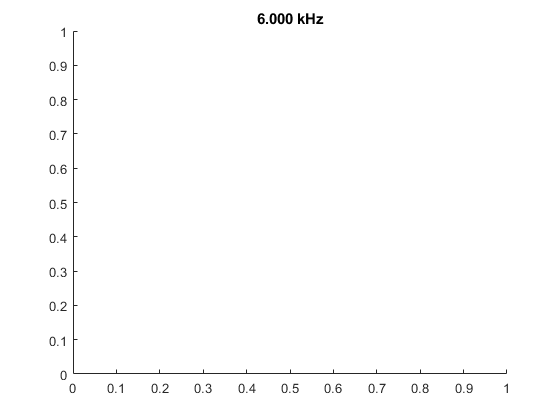


freqsFile = linspace(6000,16000,12)/1000;
numLevels = 6;
%cko4.numROI = 22;
[FRAcko13,centerFcko13,bestFcko13,respcko13,bandWcko13,maxFcko13,bandWLincko13,bandWgauscko13,traceBFcko13,traceCFcko13,bandW70cko13] = getFRA6levelsV2(cko13,numLevels,freqsFile,freqInterval);


% log spacing
freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
con1.numROI = 8;
[FRAcon1,centerFcon1,bestFcon1,respcon1,bandWcon1,maxFcon1,bandWLincon1,bandWgauscon1,traceBFcon1,traceCFcon1,bandW70con1] = getFRA6levelsV2(con1,numLevels,freqsFile,freqInterval);

error encountered index:1
error encountered index:4



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
con2.numROI = 28;
[FRAcon2,centerFcon2,bestFcon2,respcon2,bandWcon2,maxFcon2,bandWLincon2,bandWgauscon2,traceBFcon2,traceCFcon2,bandW70con2] = getFRA6levelsV2(con2,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
con3.numROI = 35;
[FRAcon3,centerFcon3,bestFcon3,respcon3,bandWcon3,maxFcon3,bandWLincon3,bandWgauscon3,traceBFcon3,traceCFcon3,bandW70con3] = getFRA6levelsV2(con3,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon6,centerFcon6,bestFcon6,respcon6,bandWcon6,maxFcon6,bandWLincon6,bandWgauscon6,traceBFcon6,traceCFcon6,bandW70con6] = getFRA6levelsV2(con6,numLevels,freqsFile,freqInterval);

error encountered index:2



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon7,centerFcon7,bestFcon7,respcon7,bandWcon7,maxFcon7,bandWLincon7,bandWgauscon7,traceBFcon7,traceCFcon7,bandW70con7] = getFRA6levelsV2(con7,numLevels,freqsFile,freqInterval);

error encountered index:3
error encountered index:4



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon8,centerFcon8,bestFcon8,respcon8,bandWcon8,maxFcon8,bandWLincon8,bandWgauscon8,traceBFcon8,traceCFcon8,bandW70con8] = getFRA6levelsV2(con8,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon9,centerFcon9,bestFcon9,respcon9,bandWcon9,maxFcon9,bandWLincon9,bandWgauscon9,traceBFcon9,traceCFcon9,bandW70con9] = getFRA6levelsV2(con9,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon10,centerFcon10,bestFcon10,respcon10,bandWcon10,maxFcon10,bandWLincon10,bandWgauscon10,traceBFcon10,traceCFcon10,bandW70con10] = getFRA6levelsV2(con10,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcon11,centerFcon11,bestFcon11,respcon11,bandWcon11,maxFcon11,bandWLincon11,bandWgauscon11,traceBFcon11,traceCFcon11,bandW70con11] = getFRA6levelsV2(con11,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko1,centerFcko1,bestFcko1,respcko1,bandWcko1,maxFcko1,bandWLincko1,bandWgauscko1,traceBFcko1,traceCFcko1,bandW70cko1] = getFRA6levelsV2(cko1,numLevels,freqsFile,freqInterval);

error encountered index:15



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
cko2.numROI = 26;
[FRAcko2,centerFcko2,bestFcko2,respcko2,bandWcko2,maxFcko2,bandWLincko2,bandWgauscko2,traceBFcko2,traceCFcko2,bandW70cko2] = getFRA6levelsV2(cko2,numLevels,freqsFile,freqInterval);

error encountered index:5



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko6,centerFcko6,bestFcko6,respcko6,bandWcko6,maxFcko6,bandWLincko6,bandWgauscko6,traceBFcko6,traceCFcko6,bandW70cko6] = getFRA6levelsV2(cko6,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko7,centerFcko7,bestFcko7,respcko7,bandWcko7,maxFcko7,bandWLincko7,bandWgauscko7,traceBFcko7,traceCFcko7,bandW70cko7] = getFRA6levelsV2(cko7,numLevels,freqsFile,freqInterval);

error encountered index:13



freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko8,centerFcko8,bestFcko8,respcko8,bandWcko8,maxFcko8,bandWLincko8,bandWgauscko8,traceBFcko8,traceCFcko8,bandW70cko8] = getFRA6levelsV2(cko8,numLevels,freqsFile,freqInterval);

error encountered index:3
error encountered index:4
error encountered index:11
error encountered index:32


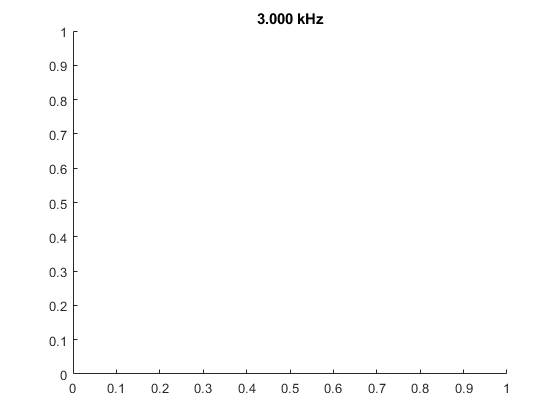


freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko9,centerFcko9,bestFcko9,respcko9,bandWcko9,maxFcko9,bandWLincko9,bandWgauscko9,traceBFcko9,traceCFcko9,bandW70cko9] = getFRA6levelsV2(cko9,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
cko10.numROI = 18;
[FRAcko10,centerFcko10,bestFcko10,respcko10,bandWcko10,maxFcko10,bandWLincko10,bandWgauscko10,traceBFcko10,traceCFcko10,bandW70cko10] = getFRA6levelsV2(cko10,numLevels,freqsFile,freqInterval);

freqsFile = logspace(log10(3000),log10(24000),12)/1000;
freqInterval = 0.27;
numLevels = 6;
[FRAcko12,centerFcko12,bestFcko12,respcko12,bandWcko12,maxFcko12,bandWLincko12,bandWgauscko12,traceBFcko12,traceCFcko12,bandW70cko12] = getFRA6levelsV2(cko12,numLevels,freqsFile,freqInterval);

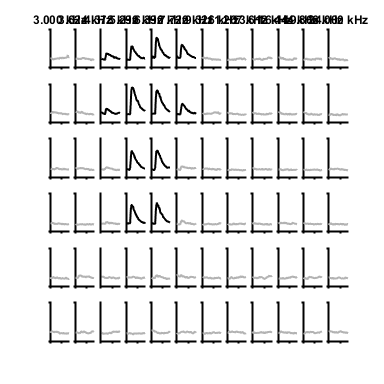

ans = 1


% plot pretty cells
numLevels = 6;
plotCells(cko2,numLevels,15,freqsFile) %11, 12, 15 cKO2

% 8, 15, 22, 25 con2
plotCells(con2,numLevels,22,freqsFile) 


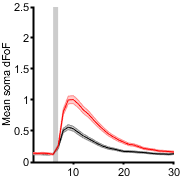

% plot mean response - by cell
% all cells - not sorted by BF, at 90-60 dB SPL
allCKOtrace = [[traceBFcko10(:).trace],[traceBFcko9(:).trace],[traceBFcko8(:).trace],[traceBFcko7(:).trace],[traceBFcko6(:).trace],[traceBFcko2(:).trace],[traceBFcko1(:).trace],[traceBFcko3(:).trace],[traceBFcko4(:).trace],[traceBFcko5(:).trace],[traceBFcko12(:).trace],[traceBFcko13(:).trace]];
allContrace = [[traceBFcon10(:).trace],[traceBFcon9(:).trace],[traceBFcon8(:).trace],[traceBFcon7(:).trace],[traceBFcon6(:).trace],[traceBFcon2(:).trace],[traceBFcon1(:).trace],[traceBFcon4(:).trace],[traceBFcon11(:).trace],[traceBFcon12(:).trace],[traceBFcon13(:).trace],[traceBFcon3(:).trace]];

meanCKOtrace = mean([allCKOtrace],2);
meanContrace = mean([allContrace],2);
stdCKOtrace = std([allCKOtrace]')/sqrt(size(allCKOtrace,2));
stdContrace = std([allContrace]')/sqrt(size(allContrace,2));

figure;
shadedErrorBar([1:1:32],meanContrace,stdContrace)
hold on
shadedErrorBar([1:1:32],meanCKOtrace,stdCKOtrace,'lineprops','r')
ylabel('Mean soma dFoF')
patch([6 6 7 7], [3 0 0 3],'k','EdgeColor','none','FaceAlpha',0.2);
%xlabel('6 kHz sound level (dB SPL)')
xlim([2 30])
figQuality(gcf,gca,[1.87 1.87])
ylim([0 2.5])
%print(gcf,'-dpdf')

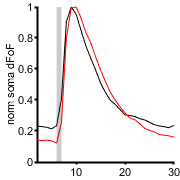


figure;
hold on
plot(meanContrace/max(meanContrace),'k')
plot(meanCKOtrace/max(meanCKOtrace),'r')
patch([6 6 7 7], [1 0 0 1],'k','EdgeColor','none','FaceAlpha',0.2);
ylabel('norm soma dFoF')
xlim([2 30])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')

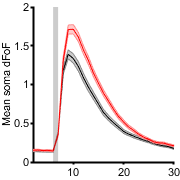


% all cells, CF trace, 90 dB 
allCKOtrace = [[traceCFcko10(:).trace],[traceCFcko9(:).trace],[traceCFcko8(:).trace],[traceCFcko7(:).trace],[traceCFcko6(:).trace],[traceCFcko2(:).trace],[traceCFcko1(:).trace],[traceCFcko3(:).trace],[traceCFcko4(:).trace],[traceCFcko5(:).trace],[traceCFcko11(:).trace],[traceCFcko12(:).trace],[traceCFcko13(:).trace]];
allContrace = [[traceCFcon10(:).trace],[traceCFcon9(:).trace],[traceCFcon8(:).trace],[traceCFcon7(:).trace],[traceCFcon6(:).trace],[traceCFcon2(:).trace],[traceCFcon1(:).trace],[traceCFcon4(:).trace],[traceCFcon5(:).trace],[traceCFcon11(:).trace],[traceCFcon12(:).trace],[traceCFcon13(:).trace],[traceCFcon3(:).trace]];

meanCKOtrace = mean([allCKOtrace],2);
meanContrace = mean([allContrace],2);
stdCKOtrace = std([allCKOtrace]')/sqrt(size(allCKOtrace,2));
stdContrace = std([allContrace]')/sqrt(size(allContrace,2));

figure;
shadedErrorBar([1:1:32],meanContrace,stdContrace)
hold on
shadedErrorBar([1:1:32],meanCKOtrace,stdCKOtrace,'lineprops','r')
ylabel('Mean soma dFoF')
patch([6 6 7 7], [3 0 0 3],'k','EdgeColor','none','FaceAlpha',0.2);
%xlabel('6 kHz sound level (dB SPL)')
xlim([2 30])
figQuality(gcf,gca,[1.87 1.87])
ylim([0 2])

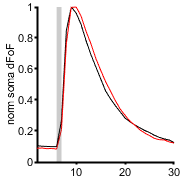

%print(gcf,'-dpdf')

figure;
hold on
plot(meanContrace/max(meanContrace),'k')
plot(meanCKOtrace/max(meanCKOtrace),'r')
patch([6 6 7 7], [1 0 0 1],'k','EdgeColor','none','FaceAlpha',0.2);
ylabel('norm soma dFoF')
xlim([2 30])
figQuality(gcf,gca,[1.87 1.87])

%print(gcf,'-dpdf')


% plot mean response - sorted by CF (log only?) 





% plot FRA distribution
FRAcon = [FRAcon1,FRAcon2,FRAcon3,FRAcon6,FRAcon7,FRAcon8,FRAcon9,FRAcon10,FRAcon11];
FRAcko = [FRAcko1,FRAcko2,FRAcko6,FRAcko7,FRAcko8,FRAcko9,FRAcko10,FRAcko12];

[h p] = kstest2(FRAcon,FRAcko);
p

p = 1.2817e-31

% how many cells? 
length(FRAcon)

ans = 157

length(FRAcko)

ans = 193

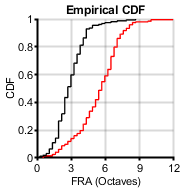


% CDF
figure
h1 = cdfplot(FRAcko);
hold on
h2 = cdfplot(FRAcon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('FRA (Octaves)');
ylabel('CDF');
xlim([0 12])
xticks([0 3 6 9 12])
figQuality(gcf,gca,[1.87 2])

p = 4.7586e-32

ans = 207

ans = 252

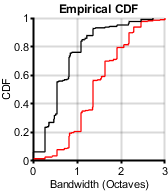


% plot bandwidth distribution
BandWcon = [bandWcon1,bandWcon2,bandWcon3,bandWcon4,bandWcon5,bandWcon6,bandWcon7,bandWcon8,bandWcon9,bandWcon10,bandWcon11];

BandWcko = [bandWcko1,bandWcko2,bandWcko3,bandWcko4,bandWcko5,bandWcko6,bandWcko7,bandWcko8,bandWcko9,bandWcko10,bandWcko12];

[h p] = kstest2(BandWcon,BandWcko);
p
% how many cells? 
length(BandWcon)
length(BandWcko)

% CDF
figure
h1 = cdfplot(BandWcko);
hold on
h2 = cdfplot(BandWcon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Bandwidth (Octaves)');
ylabel('CDF');
xlim([0 3])
xticks([0 1 2 3])
figQuality(gcf,gca,[1.75 2])

% mean band width by mouse
meanBandWcon1 = mean([bandWcon1,bandWcon6]);
meanBandWcon2 = mean([bandWcon2]);
meanBandWcon3 = nanmean([bandWcon3]);
meanBandWcon4 = mean([bandWcon4]);
meanBandWcon5 = mean([bandWcon5]);
meanBandWcon6 = nanmean([bandWcon7,bandWcon8]);
meanBandWcon7 = mean([bandWcon9,bandWcon10]);
meanBandWcon8 = nanmean([bandWcon11]);
tmemBWmean = [meanBandWcon1,meanBandWcon2,meanBandWcon3,meanBandWcon4,meanBandWcon5,meanBandWcon6,meanBandWcon7,meanBandWcon8]

tmemBWmean =     0.9441    0.6623    0.7380    0.8303    0.6593    0.4444    0.8084    0.9545


meanBandWcko1 = mean([bandWcko1,bandWcko2]);
meanBandWcko2 = mean([bandWcko3]);
meanBandWcko3 = mean([bandWcko4]);
meanBandWcko4 = mean([bandWcko5]);
meanBandWcko5 = mean([bandWcko6,bandWcko7]);
meanBandWcko6 = mean([bandWcko8,bandWcko9,bandWcko10]);
meanBandWcko7 = mean([bandWcko12]);
tectaTMBWmean = [meanBandWcko1,meanBandWcko2,meanBandWcko3,meanBandWcko4,meanBandWcko5,meanBandWcko6,meanBandWcko7]

tectaTMBWmean =     1.7162    1.3142    1.9821    1.6191    1.0529    1.4886    1.2168


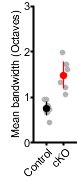

conditions2 = {'Control','cKO'};
dim = [0.8 1.87];
ylbl1 = 'Mean bandwidth (Octaves)';
[fig1 p1 h] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);
ylim([0 3])
yticks([0 1 2 3])

p1

p1 = 7.7804e-05


mean(tectaTMBWmean)

ans = 1.4843

std(tectaTMBWmean)

ans = 0.3179

mean(tmemBWmean)

ans = 0.7552

std(tmemBWmean)

ans = 0.1684

% plot gaussian bandwidth estimates 
bandWgauscon = rmmissing([bandWgauscon1,bandWgauscon2,bandWgauscon3,bandWgauscon4,bandWgauscon6,bandWgauscon7,bandWgauscon8,bandWgauscon9,bandWgauscon10,bandWgauscon11]);
bandWgauscko = rmmissing([bandWgauscko1,bandWgauscko2,bandWgauscko3,bandWgauscko4,bandWgauscko5,bandWgauscko6,bandWgauscko7,bandWgauscko8,bandWgauscko9,bandWgauscko10,bandWgauscko12]);

[h p] = kstest2(bandWgauscon,bandWgauscko);
p

p = 1.1961e-20

% how many cells? 
length(bandWgauscon)

ans = 159

length(bandWgauscko)

ans = 227

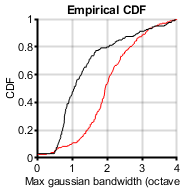


% CDF
figure
h1 = cdfplot(bandWgauscko);
hold on
h2 = cdfplot(bandWgauscon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Max gaussian bandwidth (octaves)');
ylabel('CDF');
xlim([0 4])
xticks([0 1 2 3 4])
figQuality(gcf,gca,[1.87 2])


% mean band width by mouse
meanBandWcon1 = nanmean([bandWgauscon1,bandWgauscon6]);
meanBandWcon2 = nanmean([bandWgauscon2]);
meanBandWcon3 = nanmean([bandWgauscon3]);
meanBandWcon4 = nanmean([bandWgauscon4]);
meanBandWcon6 = nanmean([bandWgauscon7,bandWgauscon8]);
meanBandWcon7 = nanmean([bandWgauscon9,bandWgauscon10]);
tmemBWmean = [meanBandWcon1,meanBandWcon2,meanBandWcon3,meanBandWcon4,meanBandWcon6,meanBandWcon7]

tmemBWmean =     1.0723    0.8272    1.4552    2.1978    1.0751    1.5084


meanBandWcko1 = nanmean([bandWgauscko1,bandWgauscko2]);
meanBandWcko2 = nanmean([bandWgauscko3]);
meanBandWcko3 = nanmean([bandWgauscko4]);
meanBandWcko4 = nanmean([bandWgauscko5]);
meanBandWcko5 = nanmean([bandWgauscko6,bandWgauscko7]);
meanBandWcko6 = nanmean([bandWgauscko8,bandWgauscko9,bandWgauscko10]);
meanBandWcko7 = nanmean([bandWgauscko12]);
tectaTMBWmean = [meanBandWcko1,meanBandWcko2,meanBandWcko3,meanBandWcko4,meanBandWcko5,meanBandWcko6,meanBandWcko7]

tectaTMBWmean =     2.1991    2.1432    1.4677    1.8453    2.2042    1.8648    2.8658


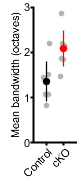

conditions2 = {'Control','cKO'};
dim = [0.8 1.87];
ylbl1 = 'Mean bandwidth (octaves)';
[fig1 p1 h] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);
ylim([0 3])
yticks([0 1 2 3])

p1

p1 = 0.0156


mean(tectaTMBWmean)

ans = 2.0843

std(tectaTMBWmean)

ans = 0.4334

mean(tmemBWmean)

ans = 1.3560

std(tmemBWmean)

ans = 0.4859

% bandwidth at 70 dB only

bandW70con = [bandW70con1,bandW70con2,bandW70con3,bandW70con4,bandW70con5,bandW70con6,bandW70con7,bandW70con8,bandW70con9,bandW70con10,bandW70con11];
bandW70cko = [bandW70cko1,bandW70cko2,bandW70cko3,bandW70cko4,bandW70cko5,bandW70cko6,bandW70cko7,bandW70cko8,bandW70cko9,bandW70cko10,bandW70cko12];

[h p] = kstest2(bandW70con,bandW70cko);
p

p = 1.1137e-54

% how many cells? 
length(bandW70con)

ans = 207

length(bandW70cko)

ans = 252

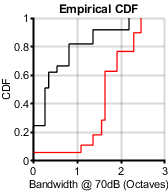


% CDF
figure
h1 = cdfplot(bandW70cko);
hold on
h2 = cdfplot(bandW70con);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Bandwidth @ 70dB (Octaves)');
ylabel('CDF');
xlim([0 3])
xticks([0 1 2 3])
figQuality(gcf,gca,[1.75 2])

% distribution of BF by frequency within field

bfCon = [bestFcon1,bestFcon2,bestFcon3,bestFcon4,bestFcon5,bestFcon6,bestFcon7,bestFcon8,bestFcon9,bestFcon10,bestFcon11];
bfCko = [bestFcko1,bestFcko2,bestFcko3,bestFcko4,bestFcko5,bestFcko6,bestFcko7,bestFcko8,bestFcko9,bestFcko10,bestFcko12];

[h p] = kstest2(bfCon,bfCko);
p

p = 7.1869e-05

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
% CDF
figure
h8 = cdfplot([bestFcko1,bestFcko2]);
hold on
h9 = cdfplot(bestFcko3);
h10 = cdfplot(bestFcko4);
h11 = cdfplot(bestFcko5);
h2 = cdfplot([bestFcon1,bestFcon6])

h2 =   Line with properties:

              Color: [0.4660 0.6740 0.1880]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 3.0000 3.0000 3.6243 3.6243 4.3784 4.3784 5.2895 5.2895 7.7200 7.7200 Inf]
              YData: [0 0 0.2308 0.2308 0.3846 0.3846 0.6154 0.6154 0.9231 0.9231 1 1]
              ZData: [1×0 double]

  Show all properties


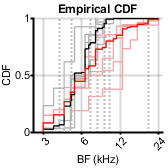

h3 = cdfplot(bestFcon2);
h4 = cdfplot(bestFcon3);
h5 = cdfplot(bestFcon4);
h6 = cdfplot(bestFcon5);
h7 = cdfplot(bfCon);
h1 = cdfplot(bfCko);
h2.Color = l_grey;
h3.Color = l_grey;
h4.Color = l_grey;
h5.Color = l_grey;
h6.Color = l_grey;
h1.Color = 'r';
h7.Color = 'k';
h8.Color = l_red;
h9.Color = l_red;
h10.Color = l_red;
h11.Color = l_red;
h1.LineWidth = 1;
h2.LineWidth = 1;
h3.LineWidth = 1;
h4.LineWidth = 1;
h5.LineWidth = 1;
h6.LineWidth = 1;
h8.LineWidth = 1;
h9.LineWidth = 1;
h10.LineWidth = 1;
h11.LineWidth = 1;
h7.LineWidth = 1;
xlabel('BF (kHz)');
ylabel('CDF');
xlim([2.5 26])
set(gca, 'xscale','log')
xticks([logspace(log10(3000),log10(24000),4)/1000])
xtickangle([45])
figQuality(gcf,gca,[1.75 1.75])



binLim = [logspace(log10(3000),log10(24000),10)/1000];
bfcon1 = histcounts([bestFcon1,bestFcon6],binLim,'Normalization','probability');
bfcon2 = histcounts(bestFcon2,binLim,'Normalization','probability');
bfcon3 = histcounts(bestFcon3,binLim,'Normalization','probability');
bfcon4 = histcounts(bestFcon4,binLim,'Normalization','probability');
bfcon5 = histcounts(bestFcon5,binLim,'Normalization','probability');
bfcon6 = histcounts([bestFcon7,bestFcon8],binLim,'Normalization','probability');
bfcon7 = histcounts([bestFcon9,bestFcon10],binLim,'Normalization','probability');
bfcon8 = histcounts(bestFcon11,binLim,'Normalization','probability');

meanbfcon = mean([bfcon1;bfcon2;bfcon3;bfcon4;bfcon5;bfcon6;bfcon7;bfcon8],1);
stdbfcon = std([bfcon1;bfcon2;bfcon3;bfcon4;bfcon5;bfcon6;bfcon7;bfcon8],1)/sqrt(8);

bfcko1 = histcounts([bestFcko1,bestFcko2],binLim,'Normalization','probability');
bfcko2 = histcounts(bestFcko3,binLim,'Normalization','probability');
bfcko3 = histcounts(bestFcko4,binLim,'Normalization','probability');
bfcko4 = histcounts(bestFcko5,binLim,'Normalization','probability');
bfcko5 = histcounts([bestFcko6,bestFcko7],binLim,'Normalization','probability');
bfcko6 = histcounts([bestFcko8,bestFcko9,bestFcko10],binLim,'Normalization','probability');
bfcko7 = histcounts(bestFcko7,binLim,'Normalization','probability');

meanbfcko = mean([bfcko1;bfcko2;bfcko3;bfcko4;bfcko5;bfcko6;bfcko7],1);
stdbfcko = std([bfcko1;bfcko2;bfcko3;bfcko4;bfcko5;bfcko6;bfcko7],1)/sqrt(6);

binLim2 = [logspace(log10(3000),log10(24000),10)/1000];
bfconHist = histcounts(bfCon,binLim2); % all data
bfckoHist = histcounts(bfCko,binLim2);

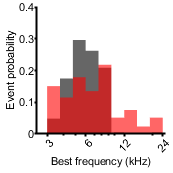


% histogram - all data
figure;
%binY = log10([0 3:1:24]);
h1 = histogram('BinCounts', bfconHist, 'BinEdges', binLim2,'FaceAlpha',0.6, 'FaceColor','k','EdgeAlpha',0); hold on;
h2 = histogram('BinCounts', bfckoHist, 'BinEdges',binLim2 ,'FaceAlpha',0.6,'FaceColor','r','EdgeAlpha',0); hold on;
%errorbar(binY(2:end)+0.01,meanTotalcountsWT(2:end),meanErrTotalWT(2:end),'vertical','linestyle','none','LineWidth',1,'Color','k','CapSize',0);
%errorbar(binY(2:end)+0.01,meanTotalcountsCKO(2:end),meanErrTotalCKO(2:end),'vertical','linestyle','none','LineWidth',1,'Color','r','CapSize',0);
h1.Normalization = 'probability';
h2.Normalization = 'probability';
ylim([0 0.4]);
yticks([0:0.1:1]);
xlim([2.5 25]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Best frequency (kHz)');
ylabel('Event probability');
figQuality(gcf,gca,[1.8 1.8])

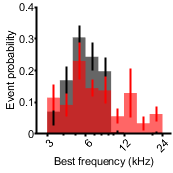

%print(gcf,'-dpdf')

binLim3 = [mean(binLim(1:2)),mean(binLim(2:3)),mean(binLim(3:4)),mean(binLim(4:5)),mean(binLim(5:6)),mean(binLim(6:7)),mean(binLim(7:8)),mean(binLim(8:9)),mean(binLim(9:10))];

figure;
%binY = log10([0 3:1:24]);
h1 = histogram('BinCounts', meanbfcon, 'BinEdges', binLim,'FaceAlpha',0.6, 'FaceColor','k','EdgeAlpha',0); hold on;
h2 = histogram('BinCounts', meanbfcko, 'BinEdges',binLim ,'FaceAlpha',0.6,'FaceColor','r','EdgeAlpha',0); hold on;
errorbar(binLim3(1:9),meanbfcon,stdbfcon,'vertical','linestyle','none','LineWidth',1.5,'Color','k','CapSize',0);
errorbar(binLim3(1:9),meanbfcko,stdbfcko,'vertical','linestyle','none','LineWidth',1.5,'Color','r','CapSize',0);
ylim([0 0.4]);
yticks([0:0.1:1]);
xlim([2.5 28]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Best frequency (kHz)');
ylabel('Event probability');
figQuality(gcf,gca,[1.8 1.8])
print(gcf,'-dpdf')


% distribution of CF by frequency within field


cfCon = [centerFcon1,centerFcon2,centerFcon3,centerFcon4,centerFcon5,centerFcon6,centerFcon7,centerFcon8,centerFcon9,centerFcon10,centerFcon11];
cfCko = [centerFcko1,centerFcko2,centerFcko3,centerFcko4,centerFcko5,centerFcko6,centerFcko7,centerFcko8,centerFcko9,centerFcko10,centerFcko12];

[h p] = kstest2(cfCon,cfCko);
p

p = 1.1214e-10

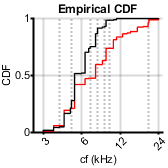


% CDF
figure
h1 = cdfplot(cfCko);
hold on
h2 = cdfplot(cfCon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('cf (kHz)');
ylabel('CDF');
xlim([2.5 26])
set(gca, 'xscale','log')
xticks([logspace(log10(3000),log10(24000),4)/1000])
xtickangle([45])
figQuality(gcf,gca,[1.75 1.75])

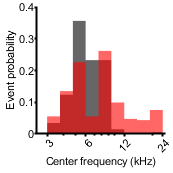


binLim = [logspace(log10(3000),log10(24000),10)/1000];
cfcon1 = histcounts([centerFcon1,centerFcon6],binLim,'Normalization','probability');
cfcon2 = histcounts(centerFcon2,binLim,'Normalization','probability');
cfcon3 = histcounts(centerFcon3,binLim,'Normalization','probability');
cfcon4 = histcounts(centerFcon4,binLim,'Normalization','probability');
cfcon5 = histcounts(centerFcon5,binLim,'Normalization','probability');
cfcon6 =  histcounts([centerFcon7,centerFcon8],binLim,'Normalization','probability');
cfcon7 =  histcounts([centerFcon9,centerFcon10],binLim,'Normalization','probability');
cfcon8 =  histcounts([centerFcon11],binLim,'Normalization','probability');

meancfcon = mean([cfcon1;cfcon2;cfcon3;cfcon4;cfcon5;cfcon6;cfcon7;cfcon8],1);
stdcfcon = std([cfcon1;cfcon2;cfcon3;cfcon4;cfcon5;cfcon6;cfcon7;cfcon8],1)/sqrt(8);

cfcko1 = histcounts([centerFcko1,centerFcko2],binLim,'Normalization','probability');
cfcko2 = histcounts(centerFcko3,binLim,'Normalization','probability');
cfcko3 = histcounts(centerFcko4,binLim,'Normalization','probability');
cfcko4 = histcounts(centerFcko5,binLim,'Normalization','probability');
cfcko5 = histcounts([centerFcko6,centerFcko7],binLim,'Normalization','probability');
cfcko6 = histcounts([centerFcko8,centerFcko9,centerFcko10],binLim,'Normalization','probability');
cfcko7 = histcounts([centerFcko12],binLim,'Normalization','probability');

meancfcko = mean([cfcko1;cfcko2;cfcko3;cfcko4;cfcko5;cfcko6;cfcko7],1);
stdcfcko = std([cfcko1;cfcko2;cfcko3;cfcko4;cfcko5;cfcko6;cfcko7],1)/sqrt(7);

binLim2 = [logspace(log10(3000),log10(24000),10)/1000];
cfconHist = histcounts(cfCon,binLim2); % all data
cfckoHist = histcounts(cfCko,binLim2);

% histogram - all data
figure;
%binY = log10([0 3:1:24]);
h1 = histogram('BinCounts', cfconHist, 'BinEdges', binLim2,'FaceAlpha',0.6, 'FaceColor','k','EdgeAlpha',0); hold on;
h2 = histogram('BinCounts', cfckoHist, 'BinEdges',binLim2 ,'FaceAlpha',0.6,'FaceColor','r','EdgeAlpha',0); hold on;
%errorbar(binY(2:end)+0.01,meanTotalcountsWT(2:end),meanErrTotalWT(2:end),'vertical','linestyle','none','LineWidth',1,'Color','k','CapSize',0);
%errorbar(binY(2:end)+0.01,meanTotalcountsCKO(2:end),meanErrTotalCKO(2:end),'vertical','linestyle','none','LineWidth',1,'Color','r','CapSize',0);
h1.Normalization = 'probability';
h2.Normalization = 'probability';
ylim([0 0.4]);
yticks([0:0.1:1]);
xlim([2.5 25]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Center frequency (kHz)');
ylabel('Event probability');
figQuality(gcf,gca,[1.8 1.8])

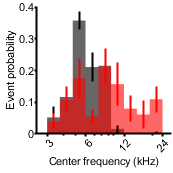

%print(gcf,'-dpdf')

binLim3 = [mean(binLim(1:2)),mean(binLim(2:3)),mean(binLim(3:4)),mean(binLim(4:5)),mean(binLim(5:6)),mean(binLim(6:7)),mean(binLim(7:8)),mean(binLim(8:9)),mean(binLim(9:10))];

figure;
%binY = log10([0 3:1:24]);
h1 = histogram('BinCounts', meancfcon, 'BinEdges', binLim,'FaceAlpha',0.6, 'FaceColor','k','EdgeAlpha',0); hold on;
h2 = histogram('BinCounts', meancfcko, 'BinEdges',binLim ,'FaceAlpha',0.6,'FaceColor','r','EdgeAlpha',0); hold on;
errorbar(binLim3(1:9),meancfcon,stdcfcon,'vertical','linestyle','none','LineWidth',1.5,'Color','k','CapSize',0);
errorbar(binLim3(1:9),meancfcko,stdcfcko,'vertical','linestyle','none','LineWidth',1.5,'Color','r','CapSize',0);
ylim([0 0.4]);
yticks([0:0.1:1]);
xlim([2.5 28]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Center frequency (kHz)');
ylabel('Event probability');
figQuality(gcf,gca,[1.8 1.8])

print(gcf,'-dpdf')


% plot all max dF/F for control and cKO
% from tuning
maxFCon = [maxFcon1,maxFcon2,maxFcon3,maxFcon4,maxFcon5,maxFcon6,maxFcon7,maxFcon8,maxFcon9,maxFcon10];
maxFCko = [maxFcko1,maxFcko2,maxFcko3,maxFcko4,maxFcko5,maxFcko6,maxFcko7,maxFcko8,maxFcko9,maxFcko10,maxFcko11];
bfCko = [bfCko,bestFcko11];

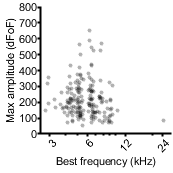


% all data
figure
% BF by max amp
hold on
%scatter(bfCko,maxFCko,20,'r','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
scatter(bfCon,maxFCon*100,10,'k','o','filled','jitter','on', 'jitterAmount',0.3,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
% from gain data
%scatter(stimVec6con,maxF6con,20,'k','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3)
%scatter(stimVec6cko,maxF6cko,20,'r','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
ylim([0 800]);
yticks([0:100:800]);
xlim([2.5 28]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Best frequency (kHz)');
ylabel('Max amplitude (dFoF)');
figQuality(gcf,gca,[1.8 1.8])
print(gcf,'-dpdf')

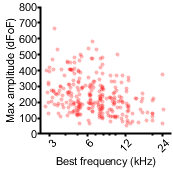


figure
% BF by max amp
hold on
scatter(bfCko,maxFCko*100,10,'r','o','filled','jitter','on', 'jitterAmount',0.3,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
%scatter(bfCon,maxFCon,20,'k','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
% from gain data
%scatter(stimVec6con,maxF6con,20,'k','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3)
%scatter(stimVec6cko,maxF6cko,20,'r','o','filled','jitter','on', 'jitterAmount',1,'MarkerFaceAlpha',0.3,'MarkerEdgeAlpha',0.3);
ylim([0 800]);
yticks([0:100:800]);
xlim([2.5 28]);
xticks([round(logspace(log10(3000),log10(24000),4)/1000)]);
xtickangle([45]);
set(gca, 'xscale','log')
%xticklabels({'0','5','10','15','20','25','>30'})
xlabel('Best frequency (kHz)');
ylabel('Max amplitude (dFoF)');
figQuality(gcf,gca,[1.8 1.8])
print(gcf,'-dpdf')


addpath('456_1 flfl','458_2 flfl','458_3 flfl','458_5 flfl','468_1 flfl','456_2 tecta flfl','458_1 tecta flfl','460_2 tecta flfl','460_3 tecta flfl','460_5 tecta flfl','460_6 tecta flfl','472_2 flfl','472_1 flfl','480_3 flfl','480_2 tecta flfl','483_2 tecta flfl','483_3 flfl','484_2 tecta flfl','486_1 flfl','486_3 flfl','486_4 tecta flfl','487_1 flfl','487_2 tecta flfl','488_1 tecta flfl')

% from gain analysis files
% 3 kHz
con1gain3 = load('C1-20211119 exp480 mouse 3  tmem16aflfl 3 khz gain R ic 10-60 db 5 db steps_ICdata.mat');
con2gain3 = load('C1-20211211 exp483 mouse 3 tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_ICdata.mat');
con3gain3 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 3 khz gain R IC 10-70 db atten 190deep_ICdata.mat'); 
con4gain3 = load('C1-20211217 exp486 mouse 3 tmem16aflfl 3 khz gain 10-60 db 5 db steps 6 reps_ICdata.mat'); 
[stimVec3con1 maxF3con1] = getMaxDF(con1gain3,3);
[stimVec3con2 maxF3con2] = getMaxDF(con2gain3,3);
[stimVec3con3 maxF3con3] = getMaxDF(con3gain3,3);
[stimVec3con4 maxF3con4] = getMaxDF(con4gain3,3);
maxF3con = [maxF3con1,maxF3con2,maxF3con3,maxF3con4];

cko1gain3 = load('C1-20211211 exp483 mouse 2 tecta tmem16a flfl 3 khz gain 10-60 db 5 db steps R IC 150 um_ICdata.mat');
cko2gain3 = load('C1-20211214 exp484 mouse2 tecta tmem16flfl 3 khz gain 10-60 db 5 db steps 6 rep_ICdata.mat');
cko3gain3 = load('C1-20211217 exp486 mouse 4 tecta tmem16aflfl 3 khz  gain R IC 10-60 db atten 150umdeep_ICdata.mat');
cko4gain3 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 3 khz gain 10-60 db atten R IC 170_ICdata.mat');
cko5gain3 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 3 khz gain 10-60db atten 4reps L IC_ICdata.mat');
[stimVec3cko1 maxF3cko1] = getMaxDF(cko1gain3,3);
[stimVec2cko2 maxF3cko2] = getMaxDF(cko2gain3,3);
[stimVec2cko3 maxF3cko3] = getMaxDF(cko3gain3,3);
[stimVec2cko4 maxF3cko4] = getMaxDF(cko4gain3,3);
[stimVec2cko5 maxF3cko5] = getMaxDF(cko5gain3,3);
maxF3cko = [maxF3cko1,maxF3cko2,maxF3cko3,maxF3cko4,maxF3cko5]; 

% 6 kHz
con1gain6 = load('C1-exp456 m1 6khz 10-60 db 5 db steps 6 reps_ICdata.mat');
con2gain6 = load('C1-exp458 m2 flfl 6 khz 4 rep 10-70 db atten 5 db steps R IC_ICdata.mat'); %458_2
con3gain6 = load('C1-exp458 m3 flfl 6 khz 6 rep 10-60 db atten 5 db steps L IC_ICdata.mat'); %458_3
con4gain6 = load('C1-exp458 m5 tmem16flfl 6 khz 4 rep 5 db steps 10-70 RIC_ICdata.mat'); %458_5
con5gain6 = load('C1-20211015 exp467 mouse 1 tmem16flfl 6 khz gain 6 rep 10-60 db atten_ICdata.mat'); %468_1
con6gain6 = load('C1-20211119 exp480 mouse 3tmem16aflfl 6 khz gain R ic 10-60 db 5 db steps_ICdata.mat'); %480_3

[stimVec6con1 maxF6con1] = getMaxDF(con1gain6,6);
[stimVec6con2 maxF6con2] = getMaxDF(con2gain6,6);
[stimVec6con3 maxF6con3] = getMaxDF(con3gain6,6);
[stimVec6con4 maxF6con4] = getMaxDF(con4gain6,6);
[stimVec6con5 maxF6con5] = getMaxDF(con5gain6,6);
[stimVec6con6 maxF6con6] = getMaxDF(con6gain6,6);
stimVec6con = [stimVec6con1,stimVec6con2,stimVec6con3,stimVec6con4,stimVec6con5,stimVec6con6];
maxF6con = [maxF6con1,maxF6con2,maxF6con3,maxF6con4,maxF6con5,maxF6con6];

cko1gain6 = load('C1-exp456 m2 6khz 10-60 db 5 db steps 6 reps 2x_ICdata.mat'); %456_2
cko2gain6 = load('C1-exp458 m1 tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %456_2
cko3gain6 = load('C1-exp460 mouse6 R IC tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_6
cko4gain6 = load('C1-exp460 mouse5 L IC tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_5
cko5gain6 = load('C1-exp460 mouse3 R IC tecta flfl 6 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat'); %460_3
cko6gain6 = load('C1-exp460 mouse2 tecta flfl 6 khz 4 rep 10-60 db atten 5 db steps_ICdata'); %460_2
cko7gain6 = load('C1-20211119 exp480 mouse 2 tecta tmem16aflfl 6 khz gain L ic 10-60 db 5 db steps_ICdata.mat'); 
cko8gain6 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 6 khz gain 10-70db atten 4reps_ICdata.mat'); 

[stimVec6cko1 maxF6cko1] = getMaxDF(cko1gain6,6);
[stimVec6cko2 maxF6cko2] = getMaxDF(cko2gain6,6);
[stimVec6cko3 maxF6cko3] = getMaxDF(cko3gain6,6);
[stimVec6cko4 maxF6cko4] = getMaxDF(cko4gain6,6);
[stimVec6cko5 maxF6cko5] = getMaxDF(cko5gain6,6);
[stimVec6cko6 maxF6cko6] = getMaxDF(cko6gain6,6);
[stimVec6cko7 maxF6cko7] = getMaxDF(cko7gain6,6);
[stimVec6cko8 maxF6cko8] = getMaxDF(cko8gain6,6);
stimVec6cko = [stimVec6cko1,stimVec6cko2,stimVec6cko3,stimVec6cko4,stimVec6cko5,stimVec6cko6,stimVec6cko7];
maxF6cko = [maxF6cko1,maxF6cko2,maxF6cko3,maxF6cko4,maxF6cko5,maxF6cko6,maxF6cko7,maxF6cko8];
% 9.5 kHz 
con1gain9 = load('C1-exp458 m2 flfl 9_5 khz 4 rep 10-70 db atten 5 db steps R IC 3_ICdata.mat'); %458_2
con2gain9 = load('C1-exp458 m5 tmem16flfl 9_5 khz 4 rep 5 db steps 10-70 RIC_ICdata.mat'); %458_5
con3gain9 = load('C1-exp458 m3 flfl 9_5 khz 6 rep 10-60 db atten 5 db steps L IC_ICdata.mat'); %458_3
con4gain9 = load('C1-20211015 exp467 mouse 1 tmem16flfl 9_5 khz gain 6 rep 10-70 db atten_ICdata.mat'); %458_3
con5gain9 = load('C1-20211103 exp472 mouse 1 tmem16aflfl 9.5 khz gain 10-70 6 rep_ICdata.mat'); %458_3
con6gain9 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 9_5 khz gain R IC 10-70 db atten 190deep_ICdata.mat'); 

[stimVec9con1 maxF9con1] = getMaxDF(con1gain9,9.5);
[stimVec9con2 maxF9con2] = getMaxDF(con2gain9,9.5);
[stimVec9con3 maxF9con3] = getMaxDF(con3gain9,9.5);
[stimVec9con4 maxF9con4] = getMaxDF(con4gain9,9.5);
[stimVec9con5 maxF9con5] = getMaxDF(con5gain9,9.5);
[stimVec9con6 maxF9con6] = getMaxDF(con6gain9,9.5);
stimVec9con = [stimVec9con1,stimVec9con2,stimVec9con3,stimVec9con4,stimVec9con5];
maxF9con = [maxF9con1,maxF9con2,maxF9con3,maxF9con4,maxF9con5,maxF9con6];

cko1gain9 = load('C1-exp460 mouse5 L IC tecta flfl 9_5 khz 6 rep 10-60 db atten 5 db steps_ICdata.mat'); %460_5
cko2gain9  = load('C1-exp458 m1 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat'); %458_1
cko3gain9  = load('C1-exp456 m2 9_5khz 10-60 db 5 db steps 6 reps 2x later_ICdata.mat'); %456_2
cko4gain9  = load('C1-exp460 mouse2 tecta flfl 9_5 khz 4 rep 10-70 db atten 5 db steps_ICdata'); %460_2
cko5gain9 = load('C1-20211220 exp487 mouse2 tecta tmem16aflfl 9.5 khz gain 10-70 db atten R IC 170_ICdata.mat'); %460_2
cko6gain9 = load('C1-20211229 exp488 mouse 1 tmem16aflfl 9.5 khz gain 10-70db atten 6reps_ICdata.mat'); %460_2

[stimVec9cko1 maxF9cko1] = getMaxDF(cko1gain9,9.5);
[stimVec9cko2 maxF9cko2] = getMaxDF(cko2gain9,9.5);
[stimVec9cko3 maxF9cko3] = getMaxDF(cko3gain9,9.5);
[stimVec9cko4 maxF9cko4] = getMaxDF(cko4gain9,9.5);
[stimVec9cko5 maxF9cko5] = getMaxDF(cko5gain9,9.5);
[stimVec9cko6 maxF9cko6] = getMaxDF(cko6gain9,9.5);
stimVec9cko = [stimVec9cko1,stimVec9cko2,stimVec9cko3,stimVec9cko4];
maxF9cko = [maxF9cko1,maxF9cko2,maxF9cko3,maxF9cko4,maxF9cko5,maxF9cko6];

% 12 kHz
con1gain12 = load('C1-20211103 exp472 mouse 2 tmem16aflfl 12 khz gain 10-70 6 rep L IC_ICdata.mat');
con2gain12 = load('C1-20211217 exp486 mouse 1 tmem16aflfl 12 khz gain R IC 10-70 db atten 190deep_ICdata.mat');
con3gain12 = load('C1-20211220 exp487 mouse1 tmem16aflfl 12 khz gain 10-70 db L IC 150 deep_ICdata.mat');

[stimVec12ccon1 maxF12con1] = getMaxDF(con1gain12,12);
[stimVec12ccon2 maxF12con2] = getMaxDF(con2gain12,12);
[stimVec12ccon3 maxF12con3] = getMaxDF(con3gain12,12);
maxF12con = [maxF12con1,maxF12con2,maxF12con3];

cko1gain12 = load('C1-exp456 m2 12khz 10-60 db 5 db steps 6 reps 2x later_ICdata.mat');
cko2gain12 = load('C1-exp458 m1 tecta flfl 12 khz 4 rep 10-70 db atten 5 db steps_ICdata.mat');
cko3gain12 = load('C1-exp460 mouse5 L IC tecta flfl 12 khz 4 rep 10-60 db atten 5 db steps_ICdata.mat');
[stimVec12cko1 maxF12cko1] = getMaxDF(cko1gain12,12);
[stimVec12cko2 maxF12cko2] = getMaxDF(cko2gain12,12);
[stimVec12cko3 maxF12cko3] = getMaxDF(cko3gain12,12);
maxF12cko = [maxF12cko1,maxF12cko2,maxF12cko3];



figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Max amplitude (% dFoF)';
dim1 = [1 2];
[fig1 p h] = compare2_extrajitter2(maxF3con*100,maxF3cko*100,conditions1,ylbl1,dim1)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 1.2909e-07

h = logical
   1


ylim([0 800])
p

p = 1.2909e-07


figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Max amplitude (% dFoF)';
dim1 = [1 2];
[fig2 p h] = compare2_extrajitter2(maxF6con*100,maxF6cko*100,conditions1,ylbl1,dim1)

not normal


fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 1.7186e-04

h = logical
   1


ylim([0 800])
p

p = 1.7186e-04


figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Max amplitude (% dFoF)';
dim1 = [1 2];
[fig3 p h] = compare2_extrajitter2(maxF9con*100,maxF9cko*100,conditions1,ylbl1,dim1)

not normal


fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 10
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 4.7945e-04

h = logical
   1


ylim([0 800])
p

p = 4.7945e-04


figure;
conditions1 = {'Control','cKO'};
ylbl1 = 'Max amplitude (% dFoF)';
dim1 = [1 2];
[fig4 p h] = compare2_extrajitter2(maxF12con*100,maxF12cko*100,conditions1,ylbl1,dim1)

not normal


fig4 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 12
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


p = 0.0062

h = logical
   1


ylim([0 800])
p

p = 0.0062

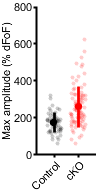

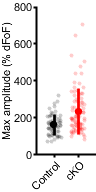

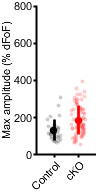

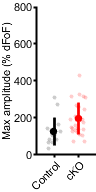


subP = handleTheSubplot({fig1,fig2,fig3,fig4},[1 4]);

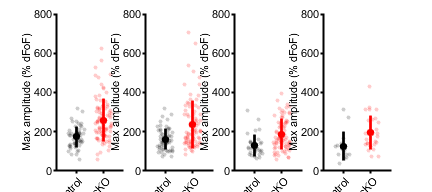

figQuality(subP,gca,[4.5 2])

% Tuning (Q factor) 
% Q factor - best frequency / maximum bandwidth

% should it be bandwidth at a lower level? 

qCon = [bestFcon1./bandWLincon1,bestFcon2./bandWLincon2,bestFcon3./bandWLincon3,bestFcon4./bandWLincon4,bestFcon5./bandWLincon5,bestFcon6./bandWLincon6,bestFcon7./bandWLincon7,bestFcon8./bandWLincon8,bestFcon9./bandWLincon9,bestFcon10./bandWLincon10];
qCko = [bestFcko1./bandWLincko1,bestFcko2./bandWLincko2,bestFcko3./bandWLincko3,bestFcko4./bandWLincko4,bestFcko5./bandWLincko5,bestFcko6./bandWLincko6,bestFcko7./bandWLincko7,bestFcko8./bandWLincko8,bestFcko9./bandWLincko9,bestFcko10./bandWLincko10,bestFcko11./bandWLincko11];

[h p] = kstest2(qCon,qCko);
p

p = 2.9953e-28

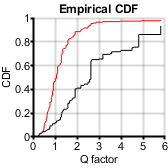


% CDF
figure
h1 = cdfplot(qCko);
hold on
h2 = cdfplot(qCon);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Q factor');
ylabel('CDF');
xlim([0 6])
%set(gca, 'xscale','log')
xticks([0 1 2 3 4 5 6])
%xtickangle([45])
figQuality(gcf,gca,[1.75 1.75])

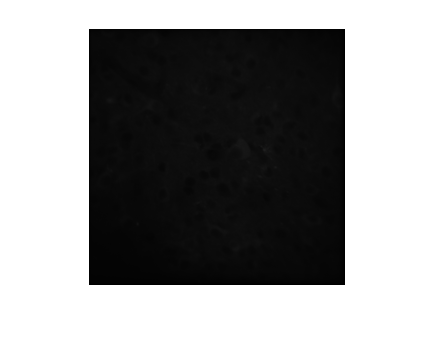

h =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties


% generate CF maps

% load max intensity image
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
imData = loadTif([pname fname], 8);
h = imshow(imData)

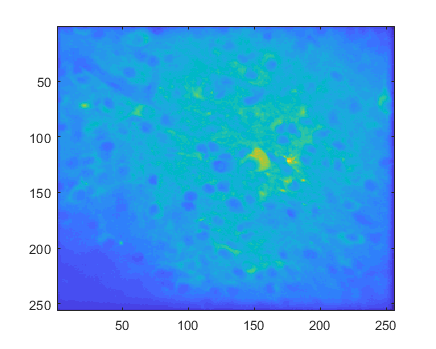

h =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


imData2 = double(imData);
h = imagesc(imData2)

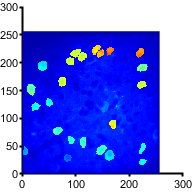

figure;
hold on;
image = zeros(256,256);
for x = 1:con11.numROI-1
    % plot ROI based on BF - color coded
    image = image + (con11.allROI{1,x}.*((log2(centerFcon11(x))-log2(3))));
end
imagesc(image);
colormap jet
caxis([0 (log2(24)-log2(3))]);
imagesc((image)+(imData2/30));
colormap jet
caxis([0 (log2(24)-log2(3))]);
figQuality(gcf,gca, [2 2]);

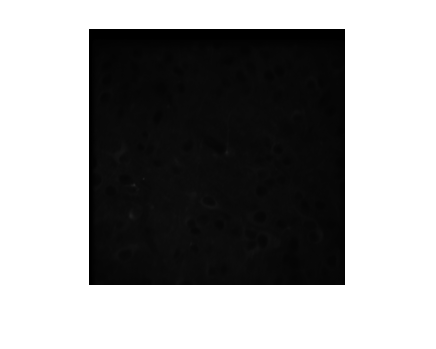

h =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties


% generate BF maps

% load max intensity image
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
imData = loadTif([pname fname], 8);
h = imshow(imData)

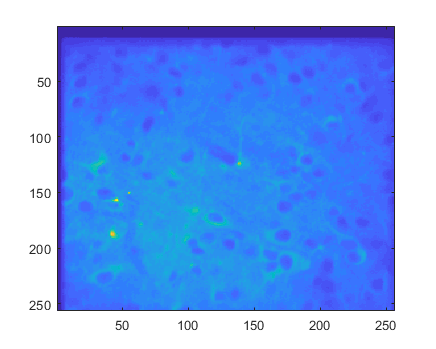

h =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


imData2 = double(imData);
h = imagesc(imData2)

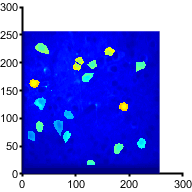

figure;
hold on;
image = zeros(256,256);
for x = 1:con9.numROI
    
    % plot ROI based on BF - color coded
    image = image + (con9.allROI{1,x}.*((log2(bestFcon9(x))-log2(3))));
end
imagesc(image);
colormap jet
caxis([0 (log2(24)-log2(3))]);
imagesc((image)+(imData2/30));
colormap jet
caxis([0 (log2(24)-log2(3))]);
figQuality(gcf,gca, [2 2]);


% load max intensity image - not quite as nice as con3
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
imData = loadTif([pname fname], 8);
h = imshow(imData)

h =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties


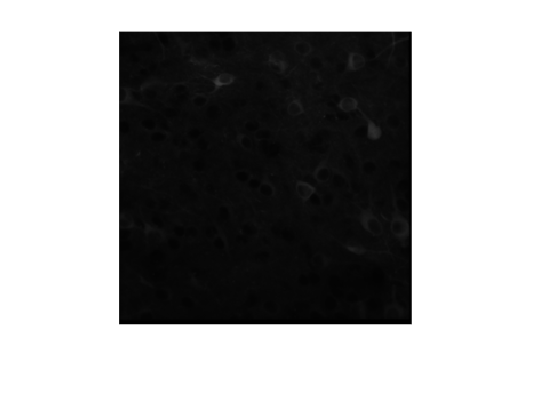

h =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


imData2 = double(imData);
h = imagesc(imData2)

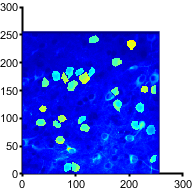

figure;
hold on;
image = zeros(256,256);
for x = 1:con2.numROI
    
    % plot ROI based on BF - color coded
    image = image + (con2.allROI{1,x}.*((log2(bestFcon2(x))-log2(3))));
end
imagesc(image);
colormap jet
caxis([0 (log2(24)-log2(3))]);
imagesc((image)+(imData2/30));
colormap jet
caxis([0 (log2(24)-log2(3))]);
figQuality(gcf,gca, [2 2]);

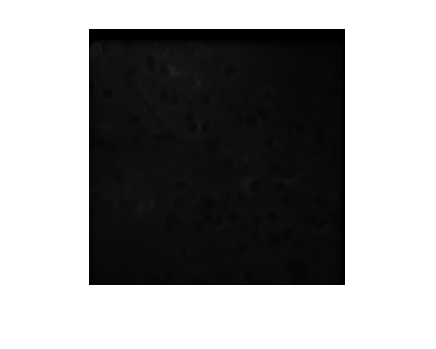

h =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties



% load max intensity image - cKO
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
imData = loadTif([pname fname], 8);
h = imshow(imData)

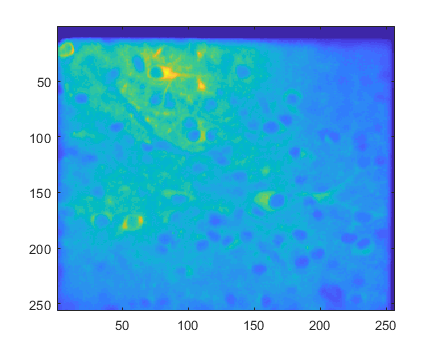

h =   Image with properties:

           CData: [256×256 double]
    CDataMapping: 'scaled'

  Show all properties


imData2 = double(imData);
h = imagesc(imData2)

figure;
hold on;
image = zeros(256,256)

image =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

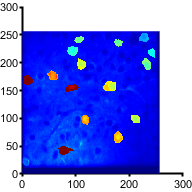

for x = 1:cko1.numROI
    % plot ROI based on BF - color coded
    image = image + (cko1.allROI{1,x}.*((log2(centerFcko1(x))-log2(3))));
end
imagesc(image)
colormap jet
caxis([0 (log2(24)-log2(3))]);
imagesc((image)+(imData2/30))
colormap jet
caxis([0 (log2(24)-log2(3))]);
figQuality(gcf,gca, [2 2])

% load and plot gain examples - with a scale
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
con90 = loadTif([pname fname], 8);
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
con70 = loadTif([pname fname], 8);
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
con40 = loadTif([pname fname], 8);
%[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
%conbase = loadTif([pname fname], 8);

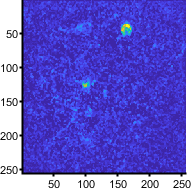


figure;
imagesc(con90)
caxis([0 50]);
colormap parula
figQuality(gcf,gca, [2 2])

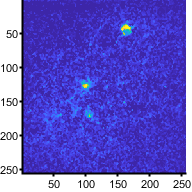

figure
imagesc(con70)
caxis([0 50]);
colormap parula
figQuality(gcf,gca, [2 2])

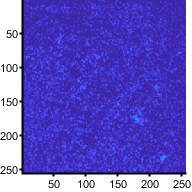

figure
imagesc(con40)
caxis([0 50]);
colormap parula
figQuality(gcf,gca, [2 2])

% cko
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
cko90 = loadTif([pname fname], 8);
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
cko70 = loadTif([pname fname], 8);
[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
cko40 = loadTif([pname fname], 8);
%[fname pname] = uigetfile({'*.tif';'*.TIF';'*.tiff';'*.TIFF'},'select the still video tiff file');
%ckobase = loadTif([pname fname], 8);

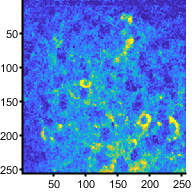


figure;
imagesc(cko90)
caxis([0 50]);
colormap parula
figQuality(gcf,gca, [2 2])

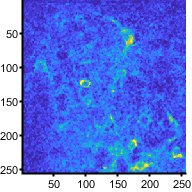

figure;
imagesc(cko70)
colormap parula
caxis([0 50]);
figQuality(gcf,gca, [2 2])

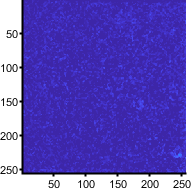

figure
imagesc(cko40)
colormap parula
caxis([0 50]);
figQuality(gcf,gca, [2 2])